cd 'D:\Program Files\Polyspace\R2021a\bin\win64\0'
tic;close all;clear all
% 读取数据
D1 = [-2.28000000000000	-3.71000000000000	-3.73000000000000	-3.63000000000000	-3.73000000000000	-0.650000000000000	-3.52000000000000	-3.21000000000000	-3.71000000000000	-3.72000000000000	-3.67000000000000	-3.64000000000000	-3.61000000000000	-3.65000000000000	-3.55000000000000	-3.54000000000000	-3.74000000000000	-3.75000000000000	-3.81000000000000	-3.76000000000000	-3.64000000000000
    -8.37000000000000	-9.48000000000000	-9.73000000000000	-9.73000000000000	-9.19000000000000	-9.68000000000000	-9.58000000000000	-2	-9.90000000000000	-9.49000000000000	-9.93000000000000	-9.24000000000000	-9.95000000000000	-9.95000000000000	-9.46000000000000	-9.32000000000000	-9.55000000000000	-10.0600000000000	-9.51000000000000	-9.77000000000000	-9.98000000000000
    -13.5000000000000	-12.4800000000000	-12.1800000000000	-13.5000000000000	-11.1800000000000	-11.3600000000000	-12.3300000000000	-12.0400000000000	-12.4100000000000	-13.7900000000000	-12.9800000000000	-12.9800000000000	-13.5300000000000	-13.4000000000000	-12.3200000000000	-11.8300000000000	-12.3900000000000	-11.6900000000000	-11.8600000000000	-13.0800000000000	-12.4000000000000
    -4.45000000000000	-5.25000000000000	-5.25000000000000	-4.57000000000000	-5.05000000000000	-5.04000000000000	-5.48000000000000	-5.84000000000000	-5.25000000000000	-5.27000000000000	-5.04000000000000	-5.48000000000000	-5.14000000000000	-5.22000000000000	-5.59000000000000	-5.39000000000000	-5.12000000000000	-5.19000000000000	-5.10000000000000	-5.19000000000000	-5.27000000000000
    0.536000000000000	0.536000000000000	0.538000000000000	0.537000000000000	0.538000000000000	0.537000000000000	0.537000000000000	0.526000000000000	0.515000000000000	0.522000000000000	0.544000000000000	0.529000000000000	0.535000000000000	0.546000000000000	0.527000000000000	0.533000000000000	0.531000000000000	0.522000000000000	0.535000000000000	0.529000000000000	0.532000000000000]';
D2 = [0	0	44.05	30.03	1.97	12.05	12.05	46.07	85.11	62.07	13.98	36.04	13	28.01	27.07	27.03	30.09	55.08	14.03	2.04	3.99
    0	0	0.46	0.51	0.4	0.41	0.45	0.11	0.29	0.04	2.75	2	0.19	2.45	4	0.05	0.14	5.16	0.08	0.55	0.7]';
D3 = [5.6	5.6	6.06	6.11	6	6.01	6.05	5.49	5.89	5.64	2.85	7.6	5.41	3.15	9.6	5.65	5.74	10.76	5.68	5.05	6.3]';
D = [D1 D2.^.5 D3.^1];
y1 = D(:,1); % MD
y2 = D(:,2); % NADH
y3 = D(:,3); % FAD
y4 = D(:,4); % CT
y5 = D(:,end); % 溶解度评分
% [num, txt] = xlsread('E:\综合评价.xlsx','Main','A41:A61');
% clear num; save('txt','txt')
%
[proteinlabel,xtick,xs] = namepdb();
cd 'D:\Program Files\Polyspace\R2021a\bin\win64\0\evaluate'
run lab01_evaluate.mlx

T1 = 8×3 table
                     标准差法     熵权法      CRITIC法
                     _______    ________    ________

    CTS              0.10786    0.044517    0.11391 
    NADH             0.11604    0.049677     0.1259 
    FAD              0.14717     0.15444    0.11208 
    MD               0.11122     0.10729    0.12304 
    亲水性            0.12236    0.097147    0.12287 
    氨基酸等电点差异    0.14015     0.17623    0.14619 
    氨基酸分子量差异    0.14448     0.29171    0.13121 
    氨基酸酸性        0.11073    0.078989     0.1248 


T2 = 4×3 table
                  标准差法      熵权法      CRITIC法 
                  ________    ________    _________

    最大值（%）     0.14717     0.29171      0.14619
    最小值（%）     0.10786    0.044517      0.11208
    差值（%）      0.039306     0.24719      0.03411
    标准差         0.015308    0.076355    0.0099169


T9 = 21×9 table
        p         s1     r1     s2     r2     s3     r3    score     rank 
    _________    ____    __    ____    __    ____    __    _____    ______

    {'5NA1' }    75.2    15    68.6    16    77.2    15    73.7     15.333
    {'WT'   }      70    19      60    21    73.7    19    67.9     19.667
    {'T352G'}    82.8     6    79.4     7    85.2     5    82.4          6
    {'T352A'}    92.9     3    88.3     6    93.8     3    91.7          4
    {'T352V'}    70.3    18    67.2    18    75.7    17    71.1     17.667
    {'T352L'}    63.8    20    69.2    15      67    20    66.7     18.333
    {'T352I'}    75.8    13    73.1    14    77.8    13    75.6     13.333
    {'T352F'}      60    21    65.4    20      60    21    61.8     20.667
    {'T352W'}    78.6    11    77.6    10    80.4    10    78.9     10.333
    {'T352Y'}    84.4     5    78.1     8    84.1     6    82.2     6.3333
    {'T352D'}    97.1     2      98     2    98.4     2    97.8          2
    {'T3

T9r = 21×9 table
        p         s1     r1     s2     r2     s3     r3    score     rank 
    _________    ____    __    ____    __    ____    __    _____    ______

    {'T352E'}     100     1     100     1     100     1     100          1
    {'T352D'}    97.1     2      98     2    98.4     2    97.8          2
    {'T352A'}    92.9     3    88.3     6    93.8     3    91.7          4
    {'T352N'}    84.6     4    77.6     9    85.4     4    82.6     5.6667
    {'T352G'}    82.8     6    79.4     7    85.2     5    82.4          6
    {'T352Y'}    84.4     5    78.1     8    84.1     6    82.2     6.3333
    {'T352H'}    82.5     7    88.4     5    81.2     8      84     6.6667
    {'T352R'}    79.5     8    96.2     3    79.2    12      85     7.6667
    {'T352C'}      79     9    75.4    11    80.6     9    78.3     9.6667
    {'T352M'}    78.9    10    73.5    13    81.8     7    78.1         10
    {'T352W'}    78.6    11    77.6    10    80.4    10    78.9     10.333
    {'T

toc

T0 = 10×21 cell 数组
    {'T352E'   }    {'T352D'   }    {'T352A'   }    {'T352N'   }    {'T352G'   }    {'T352Y'   }    {'T352H'   }    {'T352R'   }    {'T352C'   }    {'T352M'   }    {'T352W'   }    {'T352K'   }    {'T352I'   }    {'T352P'   }    {'T352S'   }    {'5NA1'    }    {'T352Q'   }    {'T352V'   }    {'T352L'   }    {'WT'      }    {'T352F'   }
    {[ -3.6500]}    {[ -3.6700]}    {[ -3.6300]}    {[ -3.6100]}    {[ -3.7300]}    {[ -3.7200]}    {[ -3.6400]}    {[ -3.7500]}    {[ -3.7600]}    {[ -3.7400]}    {[ -3.7100]}    {[ -3.5500]}    {[ -3.5200]}    {[ -3.6400]}    {[ -3.8100]}    {[ -2.2800]}    {[ -3.5400]}    {[ -3.7300]}    {[ -0.6500]}    {[ -3.7100]}    {[ -3.2100]}
    {[ -9.9500]}    {[ -9.9300]}    {[ -9.7300]}    {[ -9.9500]}    {[ -9.7300]}    {[ -9.4900]}    {[ -9.2400]}    {[-10.0600]}    {[ -9.7700]}    {[ -9.5500]}    {[ -9.9000]}    {[ -9.4600]}    {[ -9.5800]}    {[ -9.9800]}    {[ -9.5100]}    {[ -8.3700]}    {[ -9.3200]}    {[ -9.1900]}    {[ -9.6800]}   

历时 15.316118 秒。


## FAD

tic
% 输入区
ob = "fad"  % draw(ob)

ob = "fad"

## Simple

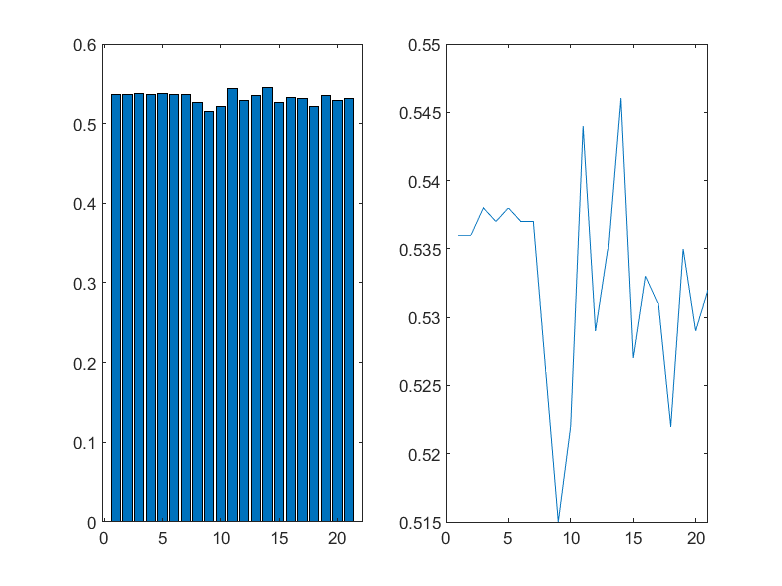

% 根本看不明白
figure
subplot(1,2,1); bar(D(:,5)); subplot(1,2,2); plot([1:21],D(:,5)')

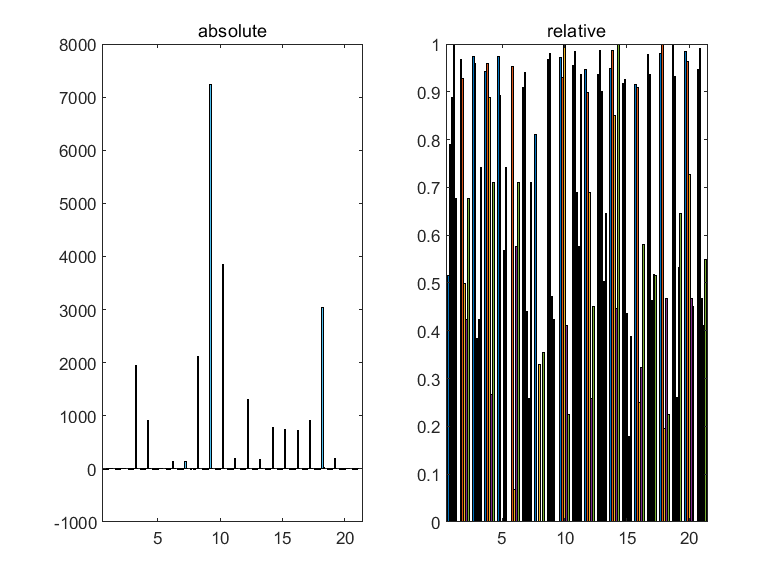

D1 = [-D(:,[1:3]) D(:,[4,5])]; % 同向化
for lgg=1:5; D2(:,lgg) = mapminmax(D1(:,lgg)',.0,1)'; end % 计算相对值
figure;subplot(1,2,1);bar(D);title('absolute');
subplot(1,2,2);bar(D2);title('relative'); hold off

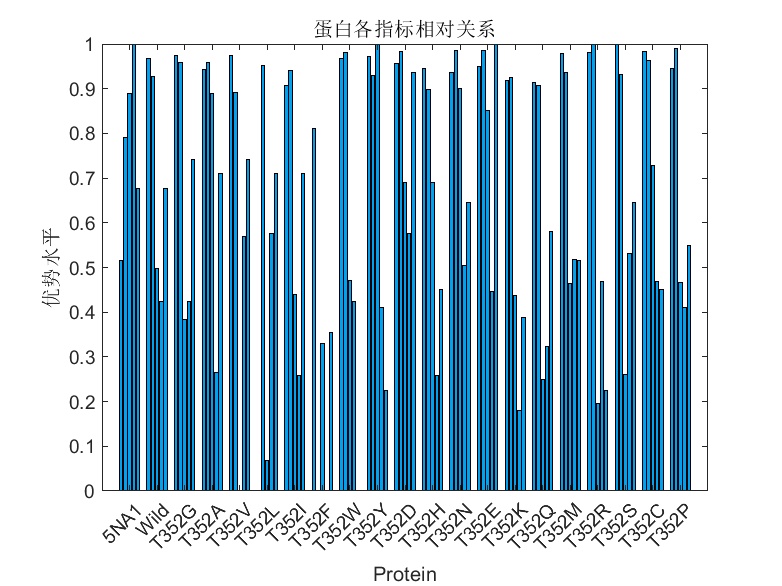

figure; b = bar(D2,'facecolor',color(3)); ylabel('优势水平'); % index relative value');
xlabel('Protein');
set(gca,'XLim',[0 22]);
set(gca,'XTick',xtick);
set(gca,'XTickLabel',proteinlabel);
title('蛋白各指标相对关系')

## Calculate

% close all
n = size(D,1) ; % 样本数量
m = zeros(n,1) ;
if1 = [y1,m,m m];
if2 = [m,y2,m m];
if3 = [m m y3 m];
if4 = [m m m y4];

## Graph 3 dots 3条纵轴

% clear;clc;close all;
% 获取到颜色
% [all_themes, all_colors] = GetColors();
all_colors = [246 83 20; 124 187 0; 0 161 241]/255;
sz = 50;
% figure;
x = 1:21;
% yyaxis left
% scatter(x, y1, 'filled');
% yyaxis right
% scatter(x, y2, 'filled');
% 三条线绘制到一起，注意数据都标准化到 y1 范围
maxY1 = max(y1); maxY2 = max(y2); maxY3 = max(y3);
minY1 = min(y1); minY2 = min(y2); minY3 = min(y3);
newY2 = (y2 - minY2)/(maxY2 - minY2);   % 归一化
newY2 = newY2*(maxY1 - minY1) + minY1;  % 反归一化
newY3 = (y3 - minY3)/(maxY3 - minY3);
newY3 = newY3*(maxY1 - minY1) + minY1;
w = 0.005; he = 0.8;
h.a = [0.1 0.1 0.57 he];
h.b = [0.68 0.1 w he];
h.c = [0.75 0.1 w he];

figure;
% title('（突变）蛋白的各项指标预测结果')
h1 = axes('position', h.a);
xlabel('Protein');
set(gca,'XLim',[0 22]);
set(gca,'XTick',xtick);
set(gca,'XTickLabel',proteinlabel);
ylabel('Binding Energy of MD/(kcal\cdotmol^{-1})');
set(gca,'ygrid','on')
% 显示数据
hold on
scatter(x, y1, sz, 'MarkerFaceColor', all_colors(1, :));
scatter(x, newY2, sz, 'MarkerFaceColor', all_colors(2, :));
scatter(x, newY3, sz, 'MarkerFaceColor', all_colors(3, :));
legend('MD','NADH','FAD','Location','best');
hold off

h1.YColor = all_colors(1, :);
% 绘制另外两个空的坐标轴
h2 = axes('position', h.b);
% 重复绘制，曲线颜色用白色，和figure背景色一致，看不出来即可
plot(x, y2, 'w')
% 颜色，位置，曲线标签
set(h2, 'ycolor', all_colors(2, :), 'yaxislocation', 'right', 'xtick', [])
% 边界显示不清楚，所以画一条线
hold on
limX2 = get(h2, 'Xlim');
limY2 = get(h2, 'Ylim');
plot([limX2(2),limX2(2)], limY2, 'Color', all_colors(2, :));
% BUG:出于未知原因，以上x轴数据不可省略，否则导致部分y轴被空白覆盖
hold off
% 取消边框
box off
ylabel('Binding Energy of NADH/(kcal\cdotmol^{-1})');
h3 = axes('position', h.c);
plot(x, y3, 'w')
set(h3, 'ycolor', all_colors(3, :), 'yaxislocation', 'right', 'xtick', [])
hold on
limX3 = get(h3, 'Xlim');
limY3 = get(h3, 'Ylim');
plot([limX3(2), limX3(2)], limY3, 'Color', all_colors(3, :));
hold off
box off
ylabel('Binding Energy of FAD/(kcal\cdotmol^{-1})');

% 取消坐标轴的颜色，和figure统一
% set(h1, 'color','none')
% set(h2, 'color','none')
% set(h3, 'color','none')
% figure背景设置成白色
set(gcf,'color','white');


## Graph Comprehansive Evaluate

% ms = mean(score(:,1:2:5),2);
rank = score(:,end');
[~,I] = sort(rank);

引用了已清除的变量 score。

% rank(I)

tic
cd 'D:\Program Files\Polyspace\R2021a\bin\win64\0\evaluate'
% run lab01_0428.mlx
tic
run lab01_evaluate
% close all
nn = 6;
ob = score(:,[1:2:nn]);
% 功效系数法将评分分布到[60 100]
score(:,[1:2:nn]) = 60+40*(ob-min(ob))./(max(ob)-min(ob));

y1 = score(:,[1:2:nn]);
y2 = score(:,[2:2:nn]);
n = size(y1,1) ; % 样本数量
h = nn/2; % 列数 column
m = zeros(n,h) ;
if1 = [y1,m];
if2 = [m,y2];

tic
figure()
cd 'D:\Program Files\Polyspace\R2021a\bin\win64\0'
left_color = color(5);
right_color = color(6);
set(figure,'defaultAxesColorOrder',[left_color; right_color]);
yl1 = '各评价方法评分';% Each Evaluation Method Scores
yl2 = '各评价方法排名';% Each Evaluation Method Ranking
yyaxis left
ylabel(yl1)
hold on
b1 = bar(if1(I,:),'FaceColor',left_color);

yyaxis right
ylabel(yl2)
b2 = bar(if2(I,:),'FaceColor',right_color);
xtick = [1:21];% 设置横坐标刻度线数值
set(gca,'XTick',xtick);
set(gca,'XTickLabel',proteinlabel(I));


xlabel('（突变）蛋白');% (Mutant) Proteins
set(gca,'ygrid','on')

p3 = plot([1:21],rank(I,:),"Color",color(4),'LineWidth',3,'LineStyle',"-.");
scatter([1:21],rank(I,:),80,[255-00 187-40 0+40]/255,'filled','s')

legend([b1(1),b2(1),p3],'得分','排名','平均位次','Location','northeast');
title('各（突变）蛋白的3种综合评价结果')% Comprehansive Evaluation of Each (Mutant) Proteins
hold off
toc




tic
cd 'D:\Program Files\Polyspace\R2021a\bin\win64\0\evaluate'
% run lab01_0428.mlx
tic
run lab01_evaluate
% close all
nn = 6;
ob = score(:,[1:2:nn]);
% 功效系数法将评分分布到[60 100]
score(:,[1:2:nn]) = 60+40*(ob-min(ob))./(max(ob)-min(ob));
y1 = score(:,[1:2:nn]);
y2 = score(:,[2:2:nn]);
n = size(y1,1) ; % 样本数量
h = nn/2; % 列数 column
m = zeros(n,h) ;
if1 = [y1,m];
if2 = [m,y2];

tic
figure()
cd 'D:\Program Files\Polyspace\R2021a\bin\win64\0'
left_color = color(5);
right_color = color(6);
set(figure,'defaultAxesColorOrder',[left_color; right_color]);
yl1 = '各评价方法评分';% Each Evaluation Method Scores
yl2 = '各评价方法排名';% Each Evaluation Method Ranking
yyaxis left
ylabel(yl1)
hold on
b1 = bar(if1,'FaceColor',left_color);

yyaxis right
ylabel(yl2)
b2 = bar(if2,'FaceColor',right_color);
xtick = [1:21];% 设置横坐标刻度线数值
set(gca,'XTick',xtick);
set(gca,'XTickLabel',proteinlabel);


xlabel('（突变）蛋白');% (Mutant) Proteins
set(gca,'ygrid','on')

p3 = plot([1:21],score(:,end'),"Color",color(4),'LineWidth',3,'LineStyle',"-.");
scatter([1:21],score(:,end'),80,[255-00 187-40 0+40]/255,'filled','s')
legend([b1(1),b2(1),p3],'得分','排名','平均位次','Location','northeast');
title('各（突变）蛋白的4种综合评价结果')% Comprehansive Evaluation of Each (Mutant) Proteins
hold off
toc


## more


% subplot(1,2,2)
% bar([1],y2(1,1)), hold on
% bar([2],y2(1,2)), hold on
% bar([3],y2(1,3)), grid on
% set(gca,'XTick',1:3,'XTickLabel',{'权威','权威','权威'})
% legend('A','B','C');
% set(gca,'FontSize',18)
% suptitle('权位职责统计')


## 分别作图（2×2）

% clear h
w = 0.005; he = 0.8;
h = [ 0.1 0.1 0.8 he
    0.68 0.1 w he
    0.75 0.1 w he ];

x = 1:21;
figure;
title('（突变）蛋白的各项指标预测结果')
hold on
ind = ["MD","NADH","FAD","S"]';
for lgg = 1:4
    %     if mod(i,2)==1
    %         j = 1
    %     else j = 2;
    %     end
    subplot(2,2,lgg)
    yyaxis left
    scatter(x, D(:,1), 'filled');
    ylabel(ind(1)+' Binding Energy/(kcal\cdotmol^{-1})');
    yyaxis right
    if lgg~=1
        scatter(x, D(:,lgg), 'filled');
        ylabel(ind(lgg)+' Binding Energy/(kcal\cdotmol^{-1})');
        if ind(lgg) == 'S'
            ylabel(ind(lgg)+' Scores');
        end
    else
        % bar([1,1],'FaceColor',[1 1 1])
        % ylabel('test','color','w')
    end
    xlabel('Protein');
    set(gca,'XLim',[0 22]);
    set(gca,'XTick',xtick);
    set(gca,'XTickLabel',proteinlabel);
    set(gca,'ygrid','on')
end
% 显示数据
hold on

function draw(ob)
lgg = 1 ; % language 1/0 中/英
% canshu
fcol = color(3);
bcol = color(5);
pcol = color(1);% [255 0 0]/255;
yylim = [
    -4 0
    -10.5 0
    -14 -10
    -6 0];
ee = [
    -3.5 -3.5
    -9.5 -9
    -13 -12
    -5 -5
    0 0 ];
for i = 1:5
    p(i,:) = [ones(1,2)*ee(i,1) ones(1,2)*ee(i,2)];
end
%
if ob == "fad"
    ii = 3;
elseif ob == "md"
    ii = 1;
elseif ob  == "nadh"
    ii = 2;
elseif ob == "ct"
    ii = 4;
else warning("ob error")
end
d = D(:,ii);
xl = [
    {'\fontname{宋体}蛋白\fontname{Times new roman}'} ...
    {'\fontname{Times new roman}Protein'} ];
yl = [
    {'\fontname{宋体}结合能\fontname{Times new roman}/(kcal\cdotmol^{-1})'} ...
    {'\fontname{Times new roman}Binding Energy/(kcal\cdotmol^{-1})'} ];
[Bd,Id] = sort(d);
figure(1)
hold on
b = bar([1:21],Bd','facecolor',fcol);
bar(find(Id==1),Bd(Id==1),'facecolor',bcol)
bar(find(Id==19),Bd(Id==19),'facecolor',bcol)

% xlabel([xl{lgg}]);
ylabel([yl{lgg}]);

% ... of FAD
set(gca,'XLim',[0 22]);
set(gca,'YLim',yylim(ii,:));
set(gca,'XTick',xtick);
set(gca,'XTickLabel',proteinlabel(Id),'FontName','Times New Roman');
set(gca,'Position',[.15 .15 .75 .75]);
% set(gca,'Position',[.05 .05 .9 .9]);
a2b = [7 5];
set(gcf,'unit','centimeters','position',[10 5 a2b*2.5]);
% plot
% hold on;
pl = plot([0 22],p(ii,[1 2]),'-.','LineWidth',3,'color',pcol);
ph = plot([0 22],p(ii,[3 4]),'-.','LineWidth',3,'color',pcol);
% title('蛋白各指标相对关系')
ax = gca;
copygraphics(ax,'ContentType','vector')
hold off
box on
toc
end

function [proteinlabel,xtick,xs] = namepdb()
load txt
proteinlabel = txt';
xtick = 1:21;
% what is the pdb's name ?
if 1==1
    proteinlabel{1} = '5NA1';
    proteinlabel{19} = 'WT';
    X = proteinlabel;
    proteinlabel = [X(1) X(19) X(2:18) X(20:end)];
end
xs = [1 21];    % x = 1:21;
end